Bandgap and Hall Effect Lab

Steven Henderson

data = readtable('bandgap and hall effect.xlsx', 'Sheet', 'Sheet1', 'Range', 'A2:C12')
V = data(:, 1)
tempV = [];

tempV =     0.2800    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6500    0.7000    0.7500    0.8000


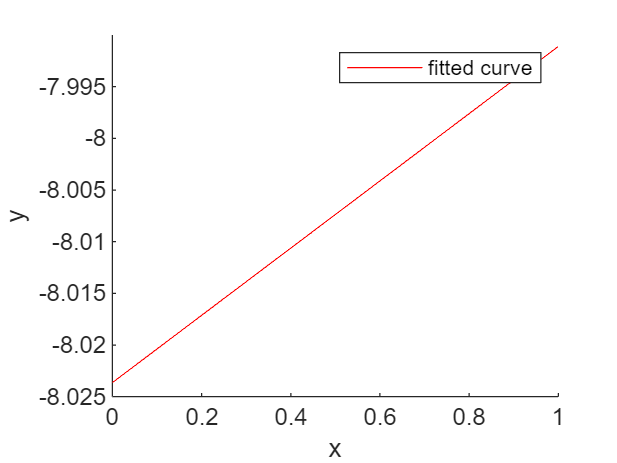

tempV_uncer = [];
current = []
current_uncer = [];
V = []; % mV 
V = V + 0.7980
V = V / 1000
V_uncer = []
l = 22;
T=273 + 100*tempV;
T_1 = T.^(-1);
w = 10;
thickness = 1;
A = l*w*thickness;
lI = l*current
VA = V*A
o = lI ./ VA
o_ln = log(o)
weights = [0.1, 0.1, 0.1, 0.1, 0.1, 0.1]
f = fit(T_1', (o_ln)', 'poly1', 'weights', weights)
plot(f)

k = 8.6*10^(-5);
- f.p1 * 2 * k